# Economics Homework 1

## Question 1:

Code:

% Define vector X
x=[1, 1.5, 3, 4, 5, 7, 9, 10];

% Compute The Values for y1=-2 + 0.5x
y1=-2 + 0.5.*x;

% Display y1
disp(y1')

   -1.5000
   -1.2500
   -0.5000
         0
    0.5000
    1.5000
    2.5000
    3.0000



% Compute the values for y2
y2= -2 + 0.5 .* x.^2;

% Display y2
disp(y2')

   -1.5000
   -0.8750
    2.5000
    6.0000
   10.5000
   22.5000
   38.5000
   48.0000



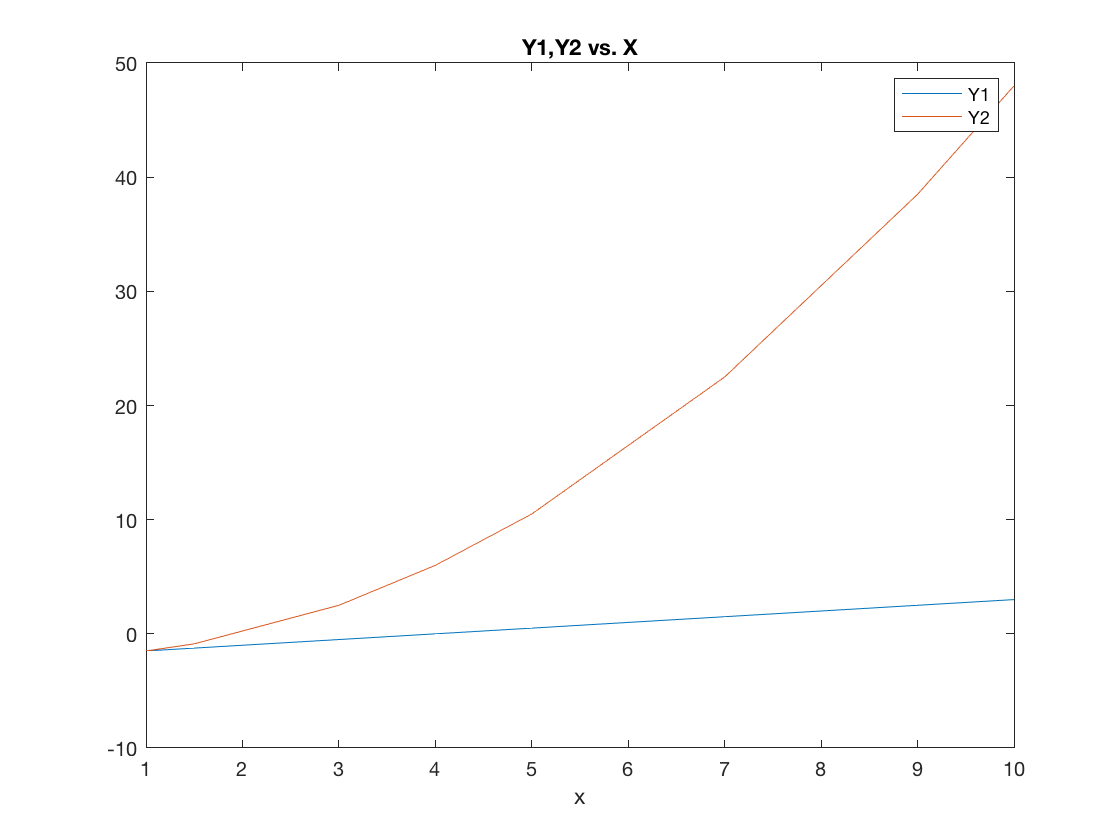


% Plot Y1, Y2 vs X
figure
plot(x, y1, x, y2)
title("Y1,Y2 vs. X")
xlabel("x")
legend("Y1", "Y2")

## Question 2

Code:

% Create x vector
x=linspace(-10, 20);

% Calculate and display sum of the elements of x
sum_x=sum(x)

sum_x = 500.0000

## Question 3

Code:

% Create A matrix
A=[2, 4, 6; 1, 7, 5; 3, 12, 4];

% Create vector b
b=[-2;3;10];

% Calculate and display C=A'b
C=A'*b;

% Calculate and display D=((A'A)^(-1))*b
D=inv(A'*A)*b

D =    -3.2505
    0.3961
    0.8037



% Calculate and Display E= sum_i (sum_j aij*bi)
E=sum(sum(A.*b))

E = 205


% F matrix is matrix with the 2nd row and 3rd column deleted

% Initialize F to A
F=A;

% Delete 2nd row
F(2,:) = [];

% Delete 3rd column and display F
F(:,3)=[]

F =      2     4
     3    12



% Solve the system Ax=b
x=A\b

x =    -0.1622
    1.2432
   -1.1081


## Question 4

Code:

% Create block diagonal matrix

% Initialize B to a 15 x 15 zero matrix
B=blkdiag(A,A,A,A,A)

B =      0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0


## Question 5

Code:

% Create 5x3 matrix of randome distributions with mu= 10 and std=5

A=10+5*randn(5,3)

A =     6.9984   -0.6918   10.6202
   12.4498    5.8021   17.1835
   13.6968   16.7730    0.1955
   18.5594    4.6392    9.0115
    9.0294   14.8048    3.9608



% Replace the elements of A that are less than 10 with 0
A(A<10)=0;

% Replace the elements of A that are equal or greater tan 10 with 1
A(A>=10)=1

A =      0     0     1
     1     0     1
     1     1     0
     1     0     0
     0     1     0


## Question 6

Code:

% Import CSV file
data = csvread('datahw1.csv');

T=readtable('datahw1.csv', 'ReadVariableNames', false);

% Modify variable names
T.Properties.VariableNames = {'FirmID', 'Year', 'Export', 'RD', 'prod', 'cap'}

T = 4392×6 table
    FirmID    Year    Export    RD     prod       cap  
    ______    ____    ______    __    _______    ______

     242       89       1       0     0.60532    11.103
     242       91       1       0     0.53529    11.103
     242       92       1       0     0.58206    11.103
     242       93       1       0     0.61332    11.103
     347       89       1       0     0.50589    10.543
     347       91       1       0     0.42298    10.543
     347       92       1       0     0.42403    10.543
     347       93       1       0     0.50085    10.543
     505       89       1       0     0.61925    10.598
     505       91       0       0     0.54382    10.598
     505       92       1       0     0.55049    10.598
     505       93       1       0     0.55762    1


fitlm(T,'prod~Export+RD+cap')

ans = Linear regression model:
    prod ~ 1 + Export + RD + cap

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)    0.082548     0.016719    4.9374      8.21e-07
    Export          0.11985    0.0063193    18.966    3.7356e-77
    RD              0.13992    0.0085321    16.399    1.0565e-58
    cap            0.029443    0.0017827    16.516    1.7144e-59


Number of observations: 4389, Error degrees of freedom: 4385
Root Mean Squared Error: 0.178
R-squared: 0.353,  Adjusted R-Squared 0.353
F-statistic vs. constant model: 798, p-value = 0